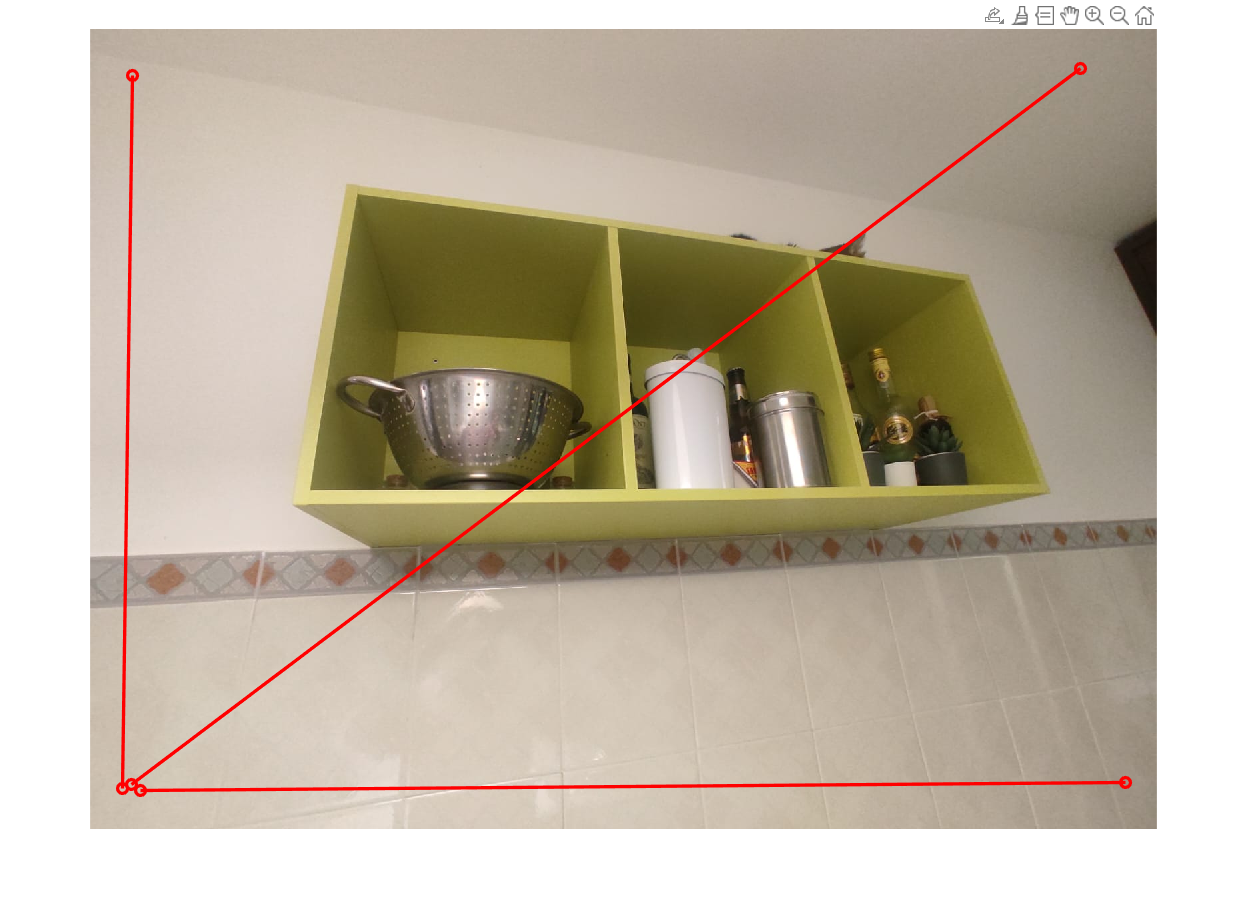

Select two points for line 1


Line 1 equation in homogeneous coordinates: [0.015386, 0.000216, -0.999882]


Select two points for line 2


Line 2 equation in homogeneous coordinates: [0.000007, 0.000875, -1.000000]


Select two points for line 3


Line 3 equation in homogeneous coordinates: [0.000639, 0.000847, -0.999999]


%% Manual Feature Extraction (lines)
% Load the image
image = imread('Look-outCat.jpg');
imshow(image);
hold on;

% Number of lines to extract
num_lines = input('Enter the number of lines to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous = zeros(3, num_lines);

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / norm(line_h);
    
    % Store the line equation
    lines_homogeneous(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
end


% Save the line equations to a .mat file for further use
save('lines_homogeneous.mat', 'lines_homogeneous');
disp('Line equations saved to lines_homogeneous.mat');

Line equations saved to lines_homogeneous.mat



%% Manual Feature Extraction (lines+2conics)

% Load the image
image = imread('Look-outCat.jpg');


% Number of lines to extract
num_lines = input('Enter the number of lines to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous = zeros(3, num_lines);

imshow(image);
hold on;

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / norm(line_h);
    
    % Store the line equation
    lines_homogeneous(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
end

Select two points for line 1


Line 1 equation in homogeneous coordinates: [0.000022, 0.001393, -0.999999]



% Save the line equations to a .mat file for further use
save('lines_homogeneous.mat', 'lines_homogeneous');
disp('Line equations saved to lines_homogeneous.mat');

Line equations saved to lines_homogeneous.mat


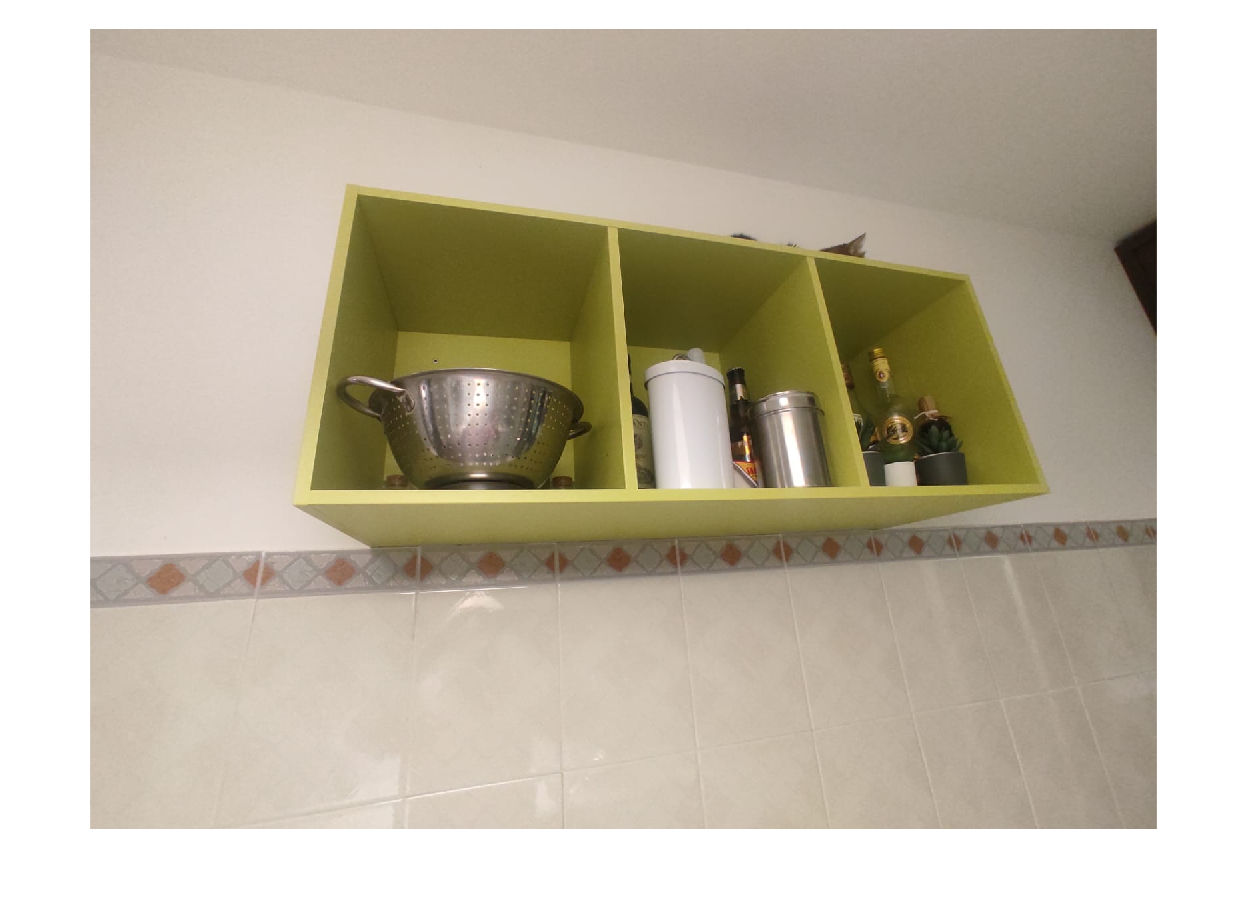

Select 6 points to define conic 1


Conic 1 matrix:


    0.0000   -0.0000   -0.0002
   -0.0000    0.0000   -0.0016
   -0.0002   -0.0016    1.0000



Select 6 points to define conic 2


Conic 2 matrix:


   -0.0000    0.0000    0.0003
    0.0000   -0.0000    0.0014
    0.0003    0.0014   -1.0000




close all;

% Number of conics to extract
num_conics = input('Enter the number of conics to extract: ');

% Initialize a cell array to store conic matrices
conics = cell(1, num_conics);
imshow(image);
hold on;

for j = 1:num_conics
    fprintf('Select 6 points to define conic %d\n', j);
    
    % Select six points using ginput
    
    [x, y] = ginput(6);
    plot(x, y, 'b-o', 'LineWidth', 2); % Show selected points on the image
    
    % Form the design matrix
    A = [x.^2, x.*y, y.^2, x, y, ones(6, 1)];
    
    % Solve for the conic parameters (up to scale)
    [~, ~, V] = svd(A);
    conic_params = V(:, end); % Last column of V corresponds to the solution
    
    % Reshape the conic parameters into a 3x3 symmetric matrix
    C = [conic_params(1), conic_params(2)/2, conic_params(4)/2; 
         conic_params(2)/2, conic_params(3), conic_params(5)/2;
         conic_params(4)/2, conic_params(5)/2, conic_params(6)];
     
    % Store the conic matrix
    conics{j} = C;
    
    fprintf('Conic %d matrix:\n', j);
    disp(C);
end


% Save the conics to a .mat file for further use
save('conics.mat', 'conics');
disp('Conic matrices saved to conics.mat');

Conic matrices saved to conics.mat


close all;

% Load the conics from the .mat file
load('conics.mat', 'conics'); % Ensure the 'conics' variable is available

% Ensure the image is loaded and displayed
figure;
imshow(image);
hold on;

% Define the resolution of the plot
t = linspace(0, 2*pi, 500); % Parameter for the ellipse

% Plot each conic
for i = 1:length(conics)
    C = conics{i}; % Get the conic matrix
    
    % Generate points on the conic
    %[X, Y] = plot_conic(C, t); 
    
    im=zeros(500,500);
    for i=1:500
        for j=1:500
            im(i,j)=[j i 1]*C*[j i 1]'; % this is an algebraic error
        end
    end

    % Plot the conic on the image
    %plot(X, Y, 'LineWidth', 2);
    %hold on;
end

title('Detected Conics');
legend('Conic 1', 'Conic 2');

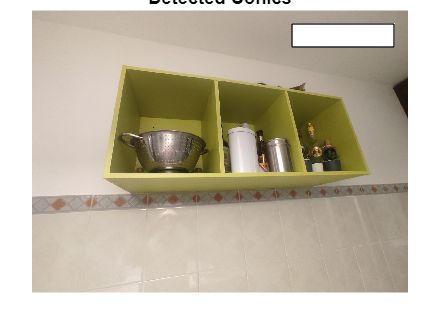

hold off;


% Function to generate (x, y) points for a conic from its matrix